1.5a,

题目要求：写出一个函数文件来表达一阶自递归方程（1.6），输出对应的处理结果

分析：用for循环输入表达式（1.6），并用数组的扩展输出每一个y[n]的值即可

结论：测试如下，函数代码见m文件

x = 1:5;
diffeqn(2,x,1)

ans =      3     8    19    42    89


1.5b,

题目要求：利用上一小问的系统，计算单位冲激函数和单位阶跃函数的响应，并用stem画出图像

分析：如题意输入函数，并绘制图像即可

x1 = [1 zeros(1,30)]

x1 =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = ones(1,31)

x2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y1 = diffeqn(1,x1,0)

y1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y2 = diffeqn(1,x2,0)

y2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31


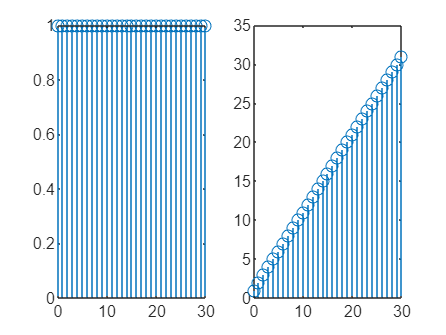

n = 0:1:30;
% 绘制图像
figure
subplot(1,2,1),stem(n,y1)
subplot(1,2,2),stem(n,y2)

1.5c,

题目要求：将单位阶跃函数进行变换后，输出对应的响应，画出图像，解释为什么变换后的两个输出的比例关系不对应输入的比例关系

分析：据题意，如下所示

x3 = x2

x3 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


x4 = 2.*x3

x4 =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


y3 = diffeqn(1,x3,-1)

y3 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


y4 = diffeqn(1,x4,-1)

y4 =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61


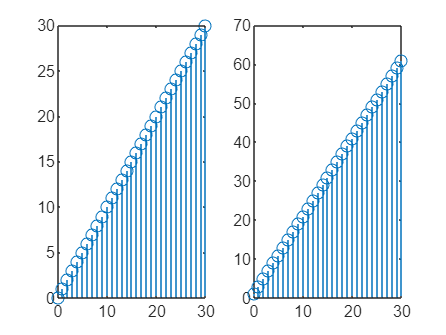

% 绘制图像
figure
subplot(1,2,1),stem(n,y3)
subplot(1,2,2),stem(n,y4)

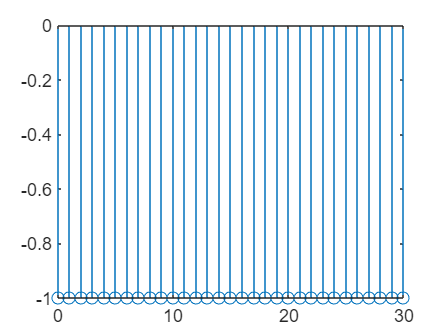

figure
stem(n,2.*y3-y4)

解释：2y1-y2的差不恒为0是因为存在一个初始参数yn1，系数yn1的存在使得两列向量由线性相关变为线性无关。

1.5d,

题目要求：展示a=0.5的两组BIBO系统的输出信号，绘制图像，观察差异

分析：如图所示，在初始阶段y坐标值受到初值影响有较大的差异，随着横坐标的增加，纵坐标值之间的差距逐渐缩小，信号图像整体呈现相同的形状特点

x5 = x2

x5 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y5 = diffeqn(0.5,x5,0)

y5 =     1.0000    1.5000    1.7500    1.8750    1.9375    1.9688    1.9844    1.9922    1.9961    1.9980    1.9990    1.9995    1.9998    1.9999    1.9999    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000


y6 = diffeqn(0.5,x5,0.5)

y6 =     1.2500    1.6250    1.8125    1.9062    1.9531    1.9766    1.9883    1.9941    1.9971    1.9985    1.9993    1.9996    1.9998    1.9999    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000


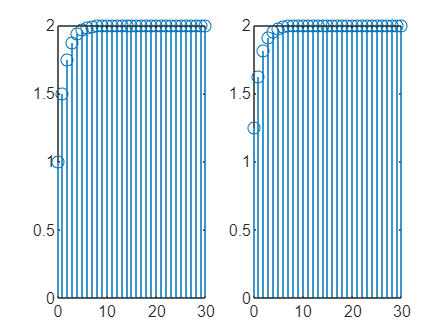

% 绘制图像
figure
subplot(1,2,1),stem(n,y5)
subplot(1,2,2),stem(n,y6)